依赖[统一实验分析作图v18.0.0](https://github.com/ShanghaitechGuanjisongLab/Unified-Experimental-Analysis-and-Figuring/releases)

热图B: leant light-water；transfer aud-water； final aud-water

DataSet=TransferLearning.FullCalcium;

排序热图2

LAFinal=UniExp.NtatsCellReplenish(DataSet.QueryNTATS(UniExp.ReadQueryTable(TransferLearning.ProjectPath('查询表.xlsx'),'Fig2B'),UniExp.Flags.dFdF0,1:24,UniExp.Flags.Median));

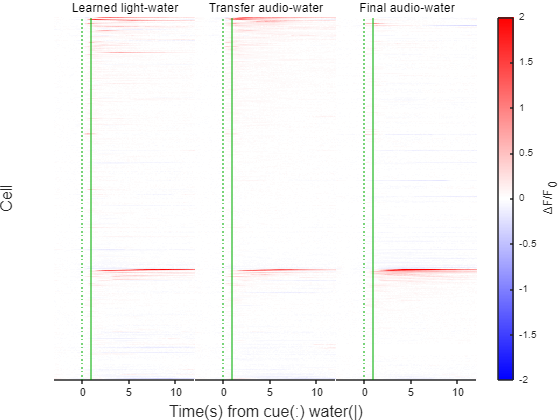

Colors=GlobalOptimization.ColorAllocate(3,[1,1,1;1,1,1]);
Data=UniExp.HeatmapSort(LAFinal,["Transfer_audio_water","Final_audio_water"],'descend').NTATS{:,:,["Learned_light_water","Transfer_audio_water","Final_audio_water"]};
Layout=TransferLearning.BasicHeatmap(Data,["Learned light-water","Transfer audio-water","Final audio-water"],Colors,false,CLim=[-2,2]);

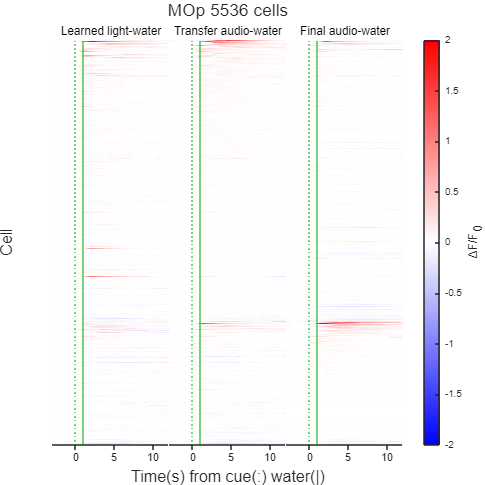

title(Layout,sprintf('MOp %u cells',height(Data)));
MATLAB.Graphics.FigureAspectRatio(1,1,1);
print(TransferLearning.ProjectPath('Fig2B.svg'),'-dsvg');

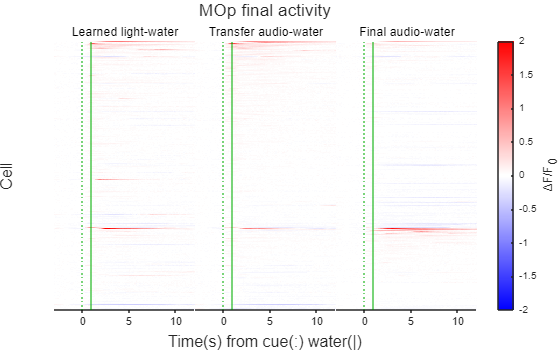

title(Layout,'MOp final activity');
MATLAB.Graphics.FigureAspectRatio(8,5,MATLAB.Flags.Narrow);
print(TransferLearning.ProjectPath('Fig2B.svg'),'-dsvg');